close all;
clear all;
clc;


fontsize=15;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('2D_rectangle');

## Parameters

### Reading the parameters from COMSOL

**Description**: This block reads the parameters from the design in COMSOL. The parameters in COMSOL are defined as global in '`Model Builder/Global Definitions/Parameters`'. The counterpart variables in Matlab follow the same names as the parameters defined in COMSOL. The parameters are first exported in COMSOL to the csv file 'parameters_2D.csv', which comprises a table where the first column refers to the parameters name, and the second column to their value. This code calls the function getVarTable  to read the value of the parameter and their units from this table. Units in this code follows the CSG units, as such units in COMSOL must be converted to CSG. For instance, the units of milimeters must be converted to meters with the factor $10^{-3}$, and similarly with the other units.

% Specify the MAT file for the parameters
csvFileName = 'parameters_2D.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);

%define and initialize to zero the parameters of interest
%geometric parameters
radius_cylinder_1=0;
width_cylinder_in_1=0;
width_cylinder_out_1=0;
angle_turn_1_rad=0;
r_in_1=0;
r_out_1=0;
L=0;%total widht of the rectangle pipe
%flow parameters
p0=0;%this is derived from COMSOL parameters if the Inlet  specify the pressure level within the Laminar Flow(spf), otherwise it must be recalculated.
v0=0;%this is derived from COMSOL parameters if the Inlet  specify the velocity level within the Laminar Flow(spf), otherwise it must be recalculated.
%Sodium parameters
c_CH3COOH_ini=0;%concentration of released particles
D_CH3COOH=0;
c_Na=0;%concentration of released particles
D_Na=0;%diffusion coefficient of released particles
d_Na=0;%diameter of the released particles
M_Na=0;%molar mass of the released particles
rho_Na=0;%density of released particles
time_delta=0;%sampling time
time_simul=0;%total simulation time
T=293.15;%default model input in Kelvin
L_inner=0;
L_outer=0;

%reading the parameters from the COMSOL file
[var,factor]=getVarTable(width_cylinder_in_1,table);
width_cylinder_in_1=eval(var{1})*factor
[var,factor]=getVarTable(width_cylinder_out_1,table);
width_cylinder_out_1=eval(var{1})*factor
[var,factor]=getVarTable(radius_cylinder_1,table);
radius_cylinder_1=eval(var{1})*factor
[var,factor]=getVarTable(angle_turn_1_rad,table);
angle_turn_1_rad=eval(var{1})*factor
[var,factor]=getVarTable(r_in_1,table);
r_in_1=eval(var{1})*factor
[var,factor]=getVarTable(r_out_1,table);
r_out_1=eval(var{1})*factor
[var,factor]=getVarTable(p0,table);
p0=eval(var{1})*factor
[var,factor]=getVarTable(v0,table);
v0=eval(var{1})*factor
[var,factor]=getVarTable(c_Na,table);
c_Na=eval(var{1})*factor
[var,factor]=getVarTable(c_CH3COOH_ini,table);
c_CH3COOH_ini=eval(var{1})*factor
[var,factor]=getVarTable(D_CH3COOH,table);
D_CH3COOH=eval(var{1})*factor
[var,factor]=getVarTable(D_Na,table);
D_Na=eval(var{1})*factor

c_CH3COONa_M = 0.0500

c_CH3COO_M = 0.0500

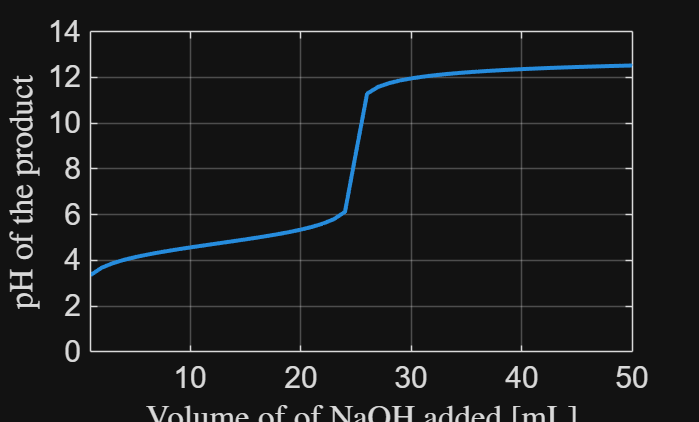

[var,factor]=getVarTable(M_Na,table);
M_Na=eval(var{1})*factor
[var,factor]=getVarTable(rho_Na,table);
rho_Na=eval(var{1})*factor
[var,factor]=getVarTable(time_delta,table);
time_delta=eval(var{1})*factor
[var,factor]=getVarTable(time_simul,table);

time_simul=eval(var{1})*factor
[var,factor]=getVarTable(L_inner,table);
L_inner=eval(var{1})*factor
[var,factor]=getVarTable(L_outer,table);
L_outer=eval(var{1})*factor


### Evaluating the water viscosity 

**Description: **This evaluates the water viscosity as follows from the analytic function in COMSOL; which is a function of the temperature. The water viscosity is found in COMSOL in '`Component 1/Geometry/Water/rho`'. In this simulation water is the fluid medium where the particles moves.

%Evaluating the water viscosity as follows from the COMSOL definition
% Specify the MAT file for the density
csvFileName = 'viscosity_H2O.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table_viscosity=readtable(csvFileName,opts);
str=table_viscosity{1,3};
mu_Water=eval(str{1})

### Evaluating the water density 

**Description: **This evaluates the water density as follows from the analytic function in COMSOL, which is a function of the temperature. The water density is found in COMSOL in '`Component 1/Geometry/Water/rho`'. In this simulation water is the fluid medium where the particles moves.

%Evaluating the water density as follows from the COMSOL definition
% Specify the MAT file for the viscosity
csvFileName = 'density_H2O.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table_density=readtable(csvFileName,opts);

%looking for the temperature range
T1=table_density{1,1};
T2=table_density{1,2};
T3=table_density{2,1};
T4=table_density{2,2};

if(T>=T1 && T<=T2)
    str=table_density{1,3};
    rho_Water=eval(str{1})
elseif(T>=T3 && T<=T4)
    str=table_density{2,3};
    rho_Water=eval(str{1})
else
    error('The temperature of your system is not in the range of COMSOL')
end


### Evaluating the input flow rate for a given pressure drop  

**Description:** This block assumes a syringe is connected to the inlet of the pipe and introduces a constant flow rate Q. The pressure formula follows the Hagen–Poiseuille equation [1, Eq. (3.1) and Table 3.1 pp. 43]

$\Delta P=\frac{8\mu L Q}{\pi r^4}$,

where 

$\mu$ is the water viscosity,

$L$ is the channel length,

$r$ is the radius of the pipe.

% Q_nL_per_min=10;
% Q=Q_nL_per_min*10^(-9)*10^(-3)/60;
% Delta_P=(8*mu_Water*L_outer)/(pi*radius_cylinder_1^4)*Q
% Delta_P_mmHg=Delta_P/133.322
%flow rate in [m^3/s]
Q_L_s=p0*(pi*radius_cylinder_1^4)/(8*mu_Water*L_outer)
%flow rate in [uL/min]
Q_uL_m=Q_L_s*60/(1e-6*1e-3)
%flow rate in [nL/min]
Q_nL_m=Q_L_s*60/(1e-9*1e-3)

## Laminar Flow

### Evaluating the flow velocity

**Description**: This section evaluates the profile velocity from theoretical formulations, which follows the Poiseuile flow. This block also contrasts results with the numerical simulation in COMSOL. The theoretcial velocity profile of the fluid within the pipe yields [2, Eq. 4.9 pag. 54]

$v(r)=\frac{\Delta p}{2\mu L}(2ry-y^2)$,

where $\Delta p$ is the inlet pressure, $\mu$ is the viscosity of the medium (water), $L$ is the length(width) of the pipe, $a$ is the radius of the pipe, and $r$ is the radial-axis coordinates. The case $r=0$ denotes the center in the cross-sectional area of the pipe.

When the inlet speed is given, it specifies the average velocity at the center of the pipe, here denoted as $\bar{v}$, and defined as $\bar{v}=\int_0^{a}{v(r)dr}=\frac{2}{3}v_\mathrm{m}$. In such a case, the resulting preasure is 

$\Delta p=\frac{3\mu L\bar{v}}{a^2}$,

and the velocity profile can be alternatively evaluated as


$$v(r)=\frac{3\bar{v}}{2a^2}(a^2-r^2)$$


#### Numerical evaluation in COMSOL

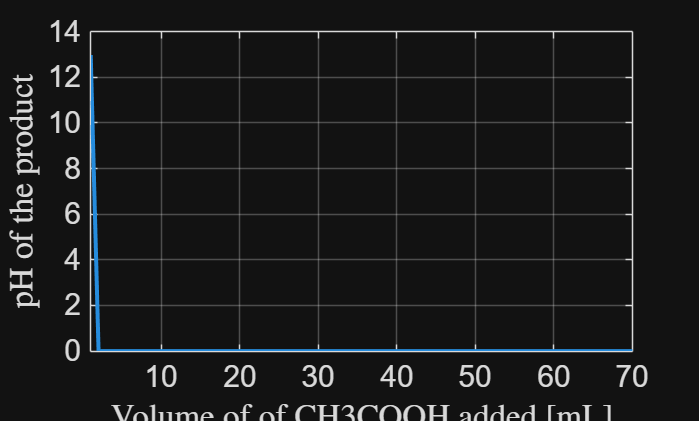

%reading the velocity profile in COMSOL

% Specify the MAT file for the velocity
csvFileName = 'velocity_vs_r.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table_velocity=readtable(csvFileName,opts);
%extracting the y-axis, this axis is shifted to the left to match the
%theoretical formulation
y_axis=table_velocity.Var2;
%the values are ordered, as COMSOL returns those unsorted
[y_axis,idx]=sort(y_axis);
v_vs_r_COMSOL=table_velocity.Var3(idx);
v_center_COMSOL=max(table_velocity.Var3)
v_mean_COMSOL=mean(table_velocity.Var3)


#### Theoretical evaluation given the inlet velocity

% syms y v
% %Given the Inlet velocity in COMSOL we evaluate the average pressure as
% p0_theo=3*mu_Water*L_inner*v_mean_COMSOL/radius_cylinder_1^2;
% %p0=8*mu_Water*L*v0/radius_cylinder_1^2;
% %For the velocity profile we follow [1, Eq. (2.33a) pp.28] except for a
% %factor of 2. This factor is correctly stated in [2, Eq. 4.9 pag. 54]
% v(y)=p0_theo/(2*mu_Water*L_inner)*(2*radius_cylinder_1*y-y^2);
% 
% v_center=double(v(radius_cylinder_1))
% %[1, Eq. (2.33a) pp.28]
% v_mean=double(int(v(y),y,0,2*radius_cylinder_1)/(2*radius_cylinder_1))


#### Theoretical evaluation given the inlet pressure

syms y v
%Given the Inlet velocity in COMSOL we evaluate the average pressure as [2, pag. 54]
p0_theo=8*mu_Water*L_inner*v_center_COMSOL/((2*radius_cylinder_1)^2)
p0_COMSOL=p0
%Evaluating the velocity profile [2, Eq. 4.9 pag. 54]
v(y)=p0_theo/(2*mu_Water*L_inner)*(2*radius_cylinder_1*y-y^2);
% v(y)=4*v_center_COMSOL/((2*radius_cylinder_1)^2)*(2*radius_cylinder_1*y-y^2);

v_center=double(v(radius_cylinder_1))
v_center_COMSOL
%[1, Eq. (2.33a) pp.28]
v_mean=double(int(v(y),y,0,2*radius_cylinder_1)/(2*radius_cylinder_1))
v_mean_COMSOL

figure;
r_vector=linspace(0,2*radius_cylinder_1,100);
plot(r_vector*10^6,double(subs(v,y,r_vector))*10^3,'LineWidth',2); grid on; hold on
plot(y_axis*10^6,v_vs_r_COMSOL*10^3,'o--','LineWidth',2,'MarkerIndices',1:5:length(v_vs_r_COMSOL),'MarkerSize',8);
xlabel('$y$-axis [$\mu$m]','Interpreter','latex');
ylabel ('Velocity [cm/s]','Interpreter','latex');
legend('Theoretical formulation','COMSOL simulation')
set(gca,'FontSize',fontsize);

## Transport of Diluted Species

### Evaluating the Reynold number

**Description:** The Reynold ($\mathrm{Re}$) number defines the ratio of inertial and viscous forces. In a microfluidic environment, where the fluid is expected to be laminar, the viscous forces dominate. Thereby we expect $\mathrm{Re}<1$.

%We evaluate the characteristic fluid speed as the mean of the fluid
v_char=(v_mean)
%We evaluate the characteristic fluid speed as the arithmetic average of
%the center and mean spead of the fluid
% v_char=sqrt(v_center*v_mean)
% v_char=sqrt(v_center_COMSOL*v_mean_COMSOL)
%This evaluation follows [1, Eq. (3.36) pp. 52]
Re=rho_Water/mu_Water*v_char*2*radius_cylinder_1

### Evaluating the Péclet number

**Description**: The Péclet ($Pe$) number defines the ratio (diffusion time)/(convection time). This ratio defines wheter diffusion or convection dominates. If the convection time is less than diffussion, then the particles haven't diffused within the convection time interval, in this case $Pe<1$. Whenever the convection time is larger than diffusion, it means that the particles has diffused before the convection time, i.e., $Pe>1$. The Péclet number is analyzed taking the diffusion time as the one needed for the particles to travel along the radius of the microfluid, i.e., given by $\tau_\mathrm{diff}^r=\frac{r^2}{D}$, where $r$ is the radius of the microfluidic pipe and $D$ is the diffusion coefficient of the particle. Similarly, is for the convection time, given by $\tau_\mathrm{conv}^r=\frac{r}{V_0}$, where $V_0$ is the average fluid velocity within the Pouseille flow.

%This evaluation follows [1,Eq. (4.44) pp.75]
Pe=radius_cylinder_1*v_char/D_CH3COOH


The particles are observed (at any point in x-axis) to diffuse homogenously whenever the condition $Pe\ll \frac{4L}{r}$ is met, where $L$ is the length of the microfluidic channel; see [1, Eq. (4.52) pp. 77]. Besides, diffusion effectively ocurred at any observation point $x$ whenever the dispersion coefficient satisfies $D_\mathrm{eff}\gg D$, where $D_\mathrm{eff}=\frac{r^2V_0^2}{48D}$ or $Pe\ll \sqrt{48}$; see [1, Eq.(4.54) pp.77].  Both conditions entails the relation:

$\sqrt{48}\ll Pe \ll 4\frac{L}{r}$.       (1)

if(Pe<4*L_inner/radius_cylinder_1)
    disp(['Concentration is constant along the x-axis'])
else
    disp(['Concentration is not constant along the x-axis, Pe=',num2str(Pe),' is larger than ',num2str(4*L_inner/radius_cylinder_1)])
end

if(Pe>sqrt(48))
    disp(['Diffusion occurred along the radial axis'])
else
    disp(['Diffusion hasn''t occurred along the axis, Pe=',num2str(Pe),' is less than ',num2str(sqrt(48))])
end

### Evaluating the Effective Diffusion

%[1, Eq.(4.54) pp.77]
D_eff=radius_cylinder_1^2*v_char^2/48/D_CH3COOH

%Evaluating the dispersion along the x axis
radius_cylinder_1^2/D_CH3COOH
%Evaluating the dispersion along the x axis
L^2/D_CH3COOH

### Straight Pipe: Evaluating the concentration level

**Description**: This section evaluates the concentration level observed at the ouptup of the rectangular pipes (straigth and turning). The evaluation is performed theoretical and following the simulations provided by COMSOL. Following COMSOL simulation we have the following files

- `CH3COOH_versus_L.csv`: This file stores the average concentration for the outlet line, which is placed at `L_inner `in the $x$ axis. The first column is time, and the concentration values are stored in the second column.

#### Theoretical evaluation of concentration in the straight channel

**Description:** Regarding the theoretical calculation we follow the Taylor's model, see [1, Sec. 4.5]. Whenever the Péclet number fulfill the condition in the above Eq. (1), the particles difussion is homogeneous along the $x$-axis and can be evaluated with the non-convection condition, i.e., free difussion in moved coordinate system. For the free difussion scenario, we regard to the case where there the diffusing substance concentrated initially on the negative side of $x'$, where $x'$ refers to the moving coordinates. The moving coordinates is along the $x$ axis of the unmoved coordinates and moves at the average speed of the velocity profile. Considering the initial conditions [3, Sec. 2.2.3 pp. 13]

$C=C_0$, $x'<0$, $C=0$, $x'>0$, $t=0$,

the solution to the diffusion equation yields [3, Eq. (2.14)]

$C(x',t)=\frac{1}{2}C_0\, \mathrm{erfc}\frac{x'}{2\sqrt{Dt}}$.             (2)

Then, within the moved coordinate system $x'=x-v_0t$ and $D=D_\mathrm{eff}$, yielding

$C(x,t)=\frac{1}{2}C_0\, \mathrm{erfc}\frac{x-v_0t}{2\sqrt{D_\mathrm{eff}\,t}}$,          (3)

where [1, Eq. (4.54) pp. 77]

$D_\mathrm{eff}=\frac{a^2v_0^2}{48D}$,                                   (4)

is the effective diffusion coefficient, and $v_0$ is the characteristic speed, here given as the average speed within the microfluidic pipe.

%Theoretical calculation
L=L_inner;%selecting the proper distance
%Matlab code to evaluate the integral
syms t z x Delta_r rd real
c=c_CH3COOH_ini*1./2.*erfc((L-v_char*t)./(2*sqrt(D_eff*t)));

%Numerical evaluation with COMSOL
% Specify the MAT file for the concentration at the outlet
csvFileName = 'CH3COOH_versus_L.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table_csv=readtable(csvFileName,opts);
time=table_csv.Var1;
c_CH3COOH_COMSOL=table_csv.Var2;

figure;
plot((time+time_delta)*10^3,subs(c,t, time+time_delta),'LineWidth',2); grid on; hold on;
plot(time(2:end)*10^3,c_CH3COOH_COMSOL(2:end),'o--','MarkerIndices',1:60:length(c_CH3COOH_COMSOL),'LineWidth',2);
% plot((time+time_delta)*10^3,gradient(double(subs(c,t, time+time_delta)),time_delta),'LineWidth',2); grid on; hold on;
% plot(time(2:end)*10^3,gradient(c_CH3COOH_COMSOL(2:end),time_delta),'--','MarkerIndices',1:400:length(c_CH3COOH_COMSOL),'LineWidth',2);
xlabel('Time [ms]','Interpreter','latex');
ylabel ('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
legend('Theoretical formulation','COMSOL simulation');
% axis([0 time_simul*10^3 0 c_CH3COOH_ini*1.1])
axis([0 time(end)*10^3 0 c_CH3COOH_ini*1.1])

### Turning Pipe: Evaluating the concentration level

**Description**: This block evaluates the concentration level for a turning pipe with the analytic formulation and validates results with the simulation in COMSOL. The COMSOL simulation includes a straigth pipe with an oblique outlet and turning pipe. The flies are the following

- `concentration_step_outlet_turn_rectangle.csv`: This file stores the average concentration for the oblique outlet in a straight pipe. The oblique segment starts at `L_inner `in the $x$ axis and ends at `L_outer`. The first column is time, and the concentration values are stored in the third column.

- `concentration_step_outlet_turn.csv`: This file stores the average concentration for the inclined outlet line. This line develops a similar condition to the outlet of the turning channel.

#### Theoretical formulation

The turning channel introduces the racetrack effect, as such, the turn is also similar to introducing an additional space-shift in the $x$-coordinate on the straight pipe. As the concentration solution en Eq. (3) is valid regardless $y$,  each lamina after the turn will be delayed in the amount $l-l_\mathrm{in}=\phi r_l - \phi r_\mathrm{in}=\phi \Delta r_l$, where $l$ refers to the length of the arcus on a given lamina, $\phi$ is the angle of the turn and $r_l$ is the radius of the arc. As such, Eq.(3) after a turn becomes

$C(x,t)=\frac{1}{2 r}\int_{r_\Delta=0}^{r_\Delta=2r}\frac{1}{2}C_0\, \mathrm{erfc}\left(\frac{x-v_0t-\phi r_\Delta}{2\sqrt{D_\mathrm{eff}\,t}}\right)dr_\Delta$ (5)

which is evaluated after using the primitive of this integral as

$\int{\mathrm{erfc}(x)dx}=x\cdot\mathrm{erfc}(x)-\frac{e^{-x^2}}{\sqrt{\pi}}$ (6)

%Matlab code to evaluate the integral
syms t x r_d r rd v varphi D C_0

% Define the substitution for x
z = (x - v*t + varphi*r_d) / (2*sqrt(D*t));

% Define the integrand
integrand = 1/2*C_0*erfc(z);

% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(2*r)*int(integrand, r_d, 0, 2*r));

% Display the result
disp('The integral of erfc(z) from r = 0 to r = 2r is:')
disp(I)
% disp(collect(I,))
disp(latex(I))
%illustrating the primitive of the integral
disp(latex(1/(2*r)*int(integrand)))


%Evaluating the function numerically
I_value=subs(I,[v,x,D,C_0,varphi,r],[v_char,L_inner,D_eff,c_CH3COOH_ini*10^3,(angle_turn_1_rad),radius_cylinder_1]);
% %Printing the numeric function with precision of two digits
% I_value_vpa=vpa(I_value,2)

% Second way (equivalent) to evaluate the integral
% c_y=c_CH3COOH_ini*1./2.*erfc((L_inner-v_char*t+(varphi)*r_d)./(2*sqrt(D_eff*t)));
% I_c_y=(1/(2*r)*int(c_y, r_d, 0, 2*r));
% I_c_y_t=subs(I_c_y,[r,varphi],[radius_cylinder_1,angle_turn_1_rad]);

%Validating the reduced closed-form expression
% c_avg=1/(2*r)*int(integrand)
c_avg=C_0/(4*r)*(erfc((x-t*v+varphi*r_d)/(2*sqrt(D*t)))*(x-t*v+varphi*r_d)-2*sqrt(D*t/pi)*exp(-(x-t*v+varphi*r_d)^2/(2*sqrt(D*t))^2))
%Replacing the constants
c_avg_value=subs(c_avg,[v,x,D,C_0,varphi,r],[v_char,L_inner,D_eff,c_CH3COOH_ini,(angle_turn_1_rad),radius_cylinder_1]);
%Evaluating the integral limits
c_avg_value_int=subs(c_avg_value,r_d,2*radius_cylinder_1)-subs(c_avg_value,r_d,0);

%Reading the concentration at the oblique outlet in the straight pipe
% Specify the MAT file for the concentration at the outlet
csvFileName = 'concentration_step_outlet_turn_rectangle.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table_csv=readtable(csvFileName,opts);
c_CH3COOH_COMSOL_rect_M=table_csv.Var2*10^3;%concentration in the units of M
time=table_csv.Var1;

%Reading the concentration at the Outlet in the turning pipe
% Specify the MAT file for the concentration at the outlet
csvFileName = 'concentration_step_outlet_turn.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table_csv=readtable(csvFileName,opts);
c_CH3COOH_COMSOL_turn_M=table_csv.Var2*10^3;%concentration in the units of M
time2=table_csv.Var1;

figure;
plot((time+time_delta)*10^3,double(subs(c_avg_value_int,t, time+time_delta)),'LineWidth',2); grid on; hold on;
% plot((time+time_delta)*10^3,double(subs(I_value,t, time+time_delta)),'LineWidth',2); grid on; hold on;
plot(time(2:end)*10^3,c_CH3COOH_COMSOL_rect_M(2:end),'--','MarkerIndices',1:60:length(c_CH3COOH_COMSOL),'LineWidth',2); hold on; grid on;
plot(time2(2:end)*10^3,c_CH3COOH_COMSOL_turn_M(2:end),'--o','MarkerIndices',30:400:length(c_CH3COOH_COMSOL_turn_M),'LineWidth',2);
xlabel('Time [ms]','Interpreter','latex');
ylabel ('Concentration [M]','Interpreter','latex');
set(gca,'FontSize',fontsize);
legend('Theoretical formulation','COMSOL simulation in straight pipe','COMSOL simulation in turning pipe');
% axis([0 time_simul*10^3 0 c_CH3COOH_ini*1.1])
axis([0 time(end)*10^3 0 c_CH3COOH_ini*1.1])

### Evaluating the impulse response in the turning channel

**Description:** This block evaluates the channel impulse response $h(t)$ for the turning channel. The $h(t)$ sequence is evaluated using the above formulation for the observed concentration of molecules. The above formulation is the step response of the channel when $C_0=1$, as such, the channel impulse response can be evaluated as [4, Eq. (7b), pp. 78]

$h(t)=\frac{\partial}{\partial t}C(x,t)\bigg|_{C_0=1}$,  (7)

where $C(x,t)$ is given as in Eq. (5) above.

%evaluating the linear transformation
h=diff(subs(c_avg,[r_d,C_0],[2*radius_cylinder_1,1])-subs(c_avg,[r_d,C_0],[0,1]),t)

% Evaluating h(t) for two different distances
L_factor=1.5;%factor to evaluate the second distance
h_value_L_1=subs(h,[v,x,D,varphi,r],[v_char,L_inner,D_eff,(angle_turn_1_rad),radius_cylinder_1]);
h_value_L_2=subs(h,[v,x,D,varphi,r],[v_char,L_factor*L_inner,D_eff,(angle_turn_1_rad),radius_cylinder_1]);
%evaluating the channel impulse response with time
h_value_vector_L_1=double(subs(h_value_L_1,t, time+time_delta));
h_value_vector_L_2=double(subs(h_value_L_2,t, time+time_delta));

% Evaluating h(t) for two different turning angles
varphi_factor=2;%factor  to evaluate the second angle
h_value_varphi_1=subs(h,[v,x,D,varphi,r],[v_char,L_inner,D_eff,(angle_turn_1_rad),radius_cylinder_1]);
h_value_varphi_2=subs(h,[v,x,D,varphi,r],[v_char,L_inner,D_eff,varphi_factor*(angle_turn_1_rad),radius_cylinder_1]);
%evaluating the channel impulse response with time
h_value_vector_varhpi_1=double(subs(h_value_varphi_1,t, time+time_delta));
h_value_vector_varphi_2=double(subs(h_value_varphi_2,t, time+time_delta));


figure;
plot((time+time_delta)*10^3,h_value_vector_L_1,'LineWidth',2); grid on; hold on;
plot((time+time_delta)*10^3,h_value_vector_L_2,'--','LineWidth',2);
xlabel('Time [ms]','Interpreter','latex');
ylabel ('$h(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);
legend({strcat('$L=',num2str(L_inner*10^3,1),'$ mm'),...
       strcat('$L=',num2str(L_factor*L_inner*10^3,1),'$ mm')},'Interpreter','latex')
axis([0 time(end)*10^3 0 max(h_value_vector_L_1)*1.1])

figure;
plot((time+time_delta)*10^3,h_value_vector_varhpi_1,'LineWidth',2); grid on; hold on;
plot((time+time_delta)*10^3,h_value_vector_varphi_2,'--','LineWidth',2);
xlabel('Time [ms]','Interpreter','latex');
ylabel ('$h(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);
legend({strcat('$\varphi=\frac{\pi}{',num2str(pi/angle_turn_1_rad),'}$ rad'),...
        strcat('$\varphi=',num2str(varphi_factor),'\frac{\pi}{',num2str(pi/angle_turn_1_rad),'}$ rad')},'Interpreter','latex')
axis([0 time(end)*10^3 0 max(h_value_vector_varphi_2)*1.1])

### Evaluating the peak amplitude and peak time at the outlet

Description: This block evaluates the peak amplitude and the peak time at the outlet of the pipe. The evaluation is performed after computing the concentration at the output as `[4, Eq. (6a), pp. 78]`


$$c_\mathrm{out}(t)=h(t)\ast c_\mathrm{in}(t),$$


where $c_\mathrm{in}(t)$ denotes the concentration at the inlet.

The concentration at the output is measured with the parameters $L$ and $\varphi$.

%Defining the parameters range
total_par=2;%total of parameters
L_par=linspace(1,2,total_par)*10^(-3);
varphi_par=linspace(pi/3,2*pi/3,total_par)*10^(-3);

%definition of the time axis
time_end=(200*10^(-3));
time=time_delta:time_delta:time_end;

%defining the inlet concentration as a rectangular function with time
n_init = 1; % Starting index
pulse_duration = 10; % Duration of the rectangular pulse in samples, each sample refers to a duration of time_delta [s]
c_in = zeros(1,pulse_duration+length(time)); % Initialize the output array
% Create the rectangular sequence
c_in(n_init:n_init+pulse_duration-1) = c_CH3COOH_ini; % Set the rectangular pulse to 1 for the defined duration

%Initial evaluation of h(t) for non-looped parameters
h_value_init = subs(h,[v,D,r],[v_char,D_eff,radius_cylinder_1]);
h_value_init = subs(h_value_init,[t],[time+time_delta]);

% Save space for the output concentration
c_out=zeros(total_par,total_par,length(c_in)+length(h_value)-1);

% Loop through the parameter ranges to evaluate c_out in parallel. We
% implement this parallel calculation as the evaluation of h_value is a
% heavy calculation.
parfor i_L = 1:total_par
   for i_varphi = 1:total_par
       %evaluating h(t) for the given parameters
       h_value = double(subs(h_value_init,[x,varphi],[L_par(i_L),varphi_par(i_varphi)]));
       %evaluating the convolution operation
       c_out(i_L,i_varphi,:)=conv(h_value',c_in,'full');
   end
end

%accounting for the differential of time in the convolution operation
c_out=c_out*time_delta;

figure;
L_select=1;
plot(time_delta*(1:length(c_out(L_select,1,:)))*10^3,c_CH3COOH_ini*reshape(c_out(L_select,1,:),1,[]),'LineWidth',2); grid on; hold on;
L_select=2;
plot(time_delta*(1:length(c_out(L_select,1,:)))*10^3,c_CH3COOH_ini*reshape(c_out(L_select,1,:),1,[]),'LineWidth',2);

xlabel('Time [ms]','Interpreter','latex');
ylabel ('$c_\mathrm{out}(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);
legend({strcat('$L=',num2str(L_par(1)*10^3,1),'$ mm'),...
       strcat('$L=',num2str(L_par(L_select)*10^3,1),'$ mm')},'Interpreter','latex')
% axis([0 time(end)*10^3 0 max(h_value_vector_L_1)*1.1])


## Evaluating the pH

Description: This block evaluates the pH of the reaction of acetic acid and sodium hydroxide in water. The evaluation of the pH follows three cases with the concentration level of both reactants. This code implements the example in [5, Example 16.5, pp. 657].

### pH when the volume of NaOH varies

%defining the concentration variables in the unit of M
c_NaOH_M=sym(0.1);
c_CH3COOH_M=sym(0.1);  
%defining the volume variables in the units of mL
v_NaOH_mL=sym(35);
v_CH3COOH_mL=sym(25);

%Ionization constant for CH3COOH, [5, Tab. 15.3, pp. 607]
Ka_CH3COOH=1.8e-5;
%Ionization constant for CH3COO-, [5, Tab. 15.3, pp. 607]
Kb_CH3COO=5.6e-10;

v_NaOH_mL=1:2*double(v_CH3COOH_mL);
pH=zeros(1,length(v_NaOH_mL));

for i=1:length(v_NaOH_mL)

    %evaluating the amount of mol per substance, [5, Examples 16.5, pp. 657]
    m_NaOH=v_NaOH_mL(i)*c_NaOH_M*1e-3;
    m_CH3COOH=v_CH3COOH_mL*c_CH3COOH_M*1e-3;

    %evaluating the case when there is more substance of CH3COOH than NaOH
    if(m_NaOH<m_CH3COOH)
        %evaluating the amount of mol left for the acid
        m_CH3COOH_prod=m_CH3COOH-m_NaOH;
        %evaluating the amount of mol for the product; which assummes that all the
        %NaOH is used in the reaction
        m_CH3COO_prod=m_NaOH;

        %evaluating the number of H+
        H_plus=m_CH3COOH_prod/m_CH3COO_prod*Ka_CH3COOH;
        %evaluating the pH
        pH(i)=-log10(H_plus);

        

        %evaluating the case when there is equal amount of both substances
    elseif(m_NaOH==m_CH3COOH)
        %Evaluating the product concentration
        c_CH3COONa_M=double(m_CH3COOH/(v_NaOH_mL(i)+v_CH3COOH_mL)*1e3)
        c_CH3COO_M=c_CH3COONa_M

        %evaluating the concentration of CH3COO-, see [5, Example 15.13, pp. 623]
        % Defining the coefficients of the quadratic polynomial
        a = sym(1); % Coefficient of x^2
        b = Kb_CH3COO; % Coefficient of x
        c = -Kb_CH3COO*c_CH3COO_M; % Constant term
        syms x
        % Solving the quadratic equation ax^2 + bx + c = 0
        solutions = solve(a*x^2 + b*x + c == 0, x);

        % Keeping only the positive solution
        c_OH_M = solutions(solutions > 0);
        p_OH=-log10(c_OH_M);
        pH(i)=double(14-p_OH);

        %when the concentration of NaOH is larger than CH3COOH
    else
        %evaluating the amount of mol for the NaOH left
        m_NaOH_prod=(v_NaOH_mL(i)-v_CH3COOH_mL)*c_NaOH_M*1e-3;
        %evaluating the concentration for the NaOH left
        c_NaOH_prod_M=m_NaOH_prod/(v_NaOH_mL(i)+v_CH3COOH_mL)*1e3;
        %evaluating the concentration of OH-
        c_OH_M=double(c_NaOH_prod_M);
        p_OH=-log10(c_OH_M);
        pH(i)=double(14-p_OH);
    end
end

figure;
plot(v_NaOH_mL,pH,'LineWidth',2); grid on;
xlabel('Volume of of NaOH added [mL]','Interpreter','latex');
ylabel ('pH of the product','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([v_NaOH_mL(1) v_NaOH_mL(end) 0 14])


### pH when the volume of CH3COOH varies

%defining the concentration variables in the unit of M
c_NaOH_M=sym(0.1);
c_CH3COOH_M=sym(0.1);  
%defining the volume variables in the units of mL
v_NaOH_mL=sym(35);
v_CH3COOH_mL=sym(25);

%Ionization constant for CH3COOH, [5, Tab. 15.3, pp. 607]
Ka_CH3COOH=1.8e-5;
%Ionization constant for CH3COO-, [5, Tab. 15.3, pp. 607]
Kb_CH3COO=5.6e-10;

v_CH3COOH_mL=1:2*double(v_NaOH_mL);
pH=zeros(1,length(v_CH3COOH_mL));

for i=1:length(v_NaOH_mL)

    %evaluating the amount of mol per substance, [5, Examples 16.5, pp. 657]
    m_NaOH=v_NaOH_mL*c_NaOH_M*1e-3;
    m_CH3COOH=v_CH3COOH_mL(i)*c_CH3COOH_M*1e-3;

    %evaluating the case when there is more substance of CH3COOH than NaOH
    if(m_NaOH<m_CH3COOH)
        %evaluating the amount of mol left for the acid
        m_CH3COOH_prod=m_CH3COOH-m_NaOH;
        %evaluating the amount of mol for the product; which assummes that all the
        %NaOH is used in the reaction
        m_CH3COO_prod=m_NaOH;

        %evaluating the number of H+
        H_plus=m_CH3COOH_prod/m_CH3COO_prod*Ka_CH3COOH;
        %evaluating the pH
        pH(i)=-log10(H_plus);

        

        %evaluating the case when there is equal amount of both substances
    elseif(m_NaOH==m_CH3COOH)
        %Evaluating the product concentration
        c_CH3COONa_M=double(m_CH3COOH/(v_NaOH_mL+v_CH3COOH_mL(i))*1e3)
        c_CH3COO_M=c_CH3COONa_M

        %evaluating the concentration of CH3COO-, see [5, Example 15.13, pp. 623]
        % Defining the coefficients of the quadratic polynomial
        a = sym(1); % Coefficient of x^2
        b = Kb_CH3COO; % Coefficient of x
        c = -Kb_CH3COO*c_CH3COO_M; % Constant term
        syms x
        % Solving the quadratic equation ax^2 + bx + c = 0
        solutions = solve(a*x^2 + b*x + c == 0, x);

        % Keeping only the positive solution
        c_OH_M = solutions(solutions > 0);
        p_OH=-log10(c_OH_M);
        pH(i)=double(14-p_OH);

        %when the concentration of NaOH is larger than CH3COOH
    else
        %evaluating the amount of mol for the NaOH left
        m_NaOH_prod=(v_NaOH_mL-v_CH3COOH_mL(i))*c_NaOH_M*1e-3;
        %evaluating the concentration for the NaOH left
        c_NaOH_prod_M=m_NaOH_prod/(v_NaOH_mL+v_CH3COOH_mL(i))*1e3;
        %evaluating the concentration of OH-
        c_OH_M=double(c_NaOH_prod_M);
        p_OH=-log10(c_OH_M);
        pH(i)=double(14-p_OH);
    end
end

figure;
plot(v_CH3COOH_mL,pH,'LineWidth',2); grid on;
xlabel('Volume of of CH3COOH added [mL]','Interpreter','latex');
ylabel ('pH of the product','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([v_CH3COOH_mL(1) v_CH3COOH_mL(end) 0 14])

%intermidiate evaluation of the parameters
h_value_init = subs(h,[varphi,v,D,r],[pi/3,v_char,D_eff,radius_cylinder_1]);


% Loop through the parameter ranges to evaluate the c_out
for i_L = 1:total_par
   
       %evaluating h(t) for the given parameters
       h_value = subs(h_value_init,[x],[L_par(i_L)]);
       %evaluating h(t) as a vector with time
       h_value_t = double(subs(h_value,t, time+time_delta));
       %evaluating the convolution operation
       c_out(i_L,i_varphi,:)=conv(h_value_t',c_in);
   
end
%accounting for the differential of time in the convolution operation
c_out=c_out*time_delta;


function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] J. Crank. 1986. The Mathematics of Diffusion. Oxford University Press.

[4] A. B. Carlson, P. B. Crilly, and J. C. Rutledge, Communication Systems: An Introduction to Signals and Noise in Electrical Communication, 4th ed. New York City, NY: McGraw-Hill, 2002, p. 850.

[5] R. Chang, *Chemistry*. Boston, Mass.: McGraw-Hill Education, 1998.  